# **Homework 3 Orbital Dynamics**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

### Data of the problem:

close all; clear; clc;

% Earth constants
mu_Earth = 398600;             % [km^3/s^2]
R_Earth = 6371;                % [km] 

% Orbital parameters
zeta_P = 350;                  % [km] distance from Earth surface to pericenter
ecc = 0.1;                     % [-] eccentricity of the satellite
RAAN = deg2rad(195);           % [rad] right ascension of the ascending node
i_orb = deg2rad(54);           % [rad] inclination
omega = deg2rad(235);          % [rad] argument of pericenter
theta = deg2rad(20);           % [rad] true anomaly

% Statistical model parameters
N = 30;                        % Number of pieces    
vel_sigma = 0.1;               % [km/s] V standard deviation

mu_log_bc = log(20);           % Mean of ln(bc), bc in [kg/m^2]
log_bc_sigma = 0.5;            % Std dev of ln(bc)

### a) Explotion function: 

The initial position of all the debris fragments is set equal to the satellite's position at the moment of the explosion, computed using $\texttt{coe2vr}$ from the given orbital elements. This gives a (3xN) matrix r0 where all columns are identical.

The function $\texttt{explosion(mu_v,sigma_v,mu_bc,sigma_bc)}$ generates the initial conditions for velocity and ballistic coefficients of the debris cloud.

The seed $\texttt{rng('default')}$ has been fixed as per request of the statement, ensuring repordducibility across runs.

r_p_orb = R_Earth + zeta_P;   % [km] pericenter radius
a_sc = r_p_orb / (1 - ecc);      % [km] semi-major axis

% [km, km/s] position and velocity vector
[r, v] = functionshw3.coe2rv(a_sc, ecc, RAAN, i_orb, omega, theta, mu_Earth); 

mu_v = v;  % [km/s]

r0 = r * ones(1, N); % [km] (3×N) initial positions

% [km/s, log(kg/m^2)] velocities and ballistic coefficient arrays
[v0, bc] = functionshw3.explosion(mu_v,vel_sigma,mu_log_bc,log_bc_sigma);   

### b)  Drag Acceleration Function

The function $\texttt{drag_acceleration(zetap_sat, v, bc)}$ computes the acceleration vector (in $km/s^2$) experienced by a fragment due to atmospheric drag, where the atmospheric density follows a simple isothermal exponential model.

If the fragment's altitude falls **below 100 km**, the function returns $\texttt{Nan}$. This avoids unphysical extrapolation of the density model into the dense lower atmosphere, and effectively flags re-entered fragments, which are removed from the plots.

% ap = functionshw3.drag_acceleration(zetap_sat, v, bc)

### c) J2 Acceleration Formula

The function $\texttt{J2_acceleration(r)}$ computes the perturbation acceleration (in $km/s^2$) due to Earth's oblateness, characterised by the second zonal harmonic $J_2 = 1.08263 \times 10^{-3}$. This perturbation has two components:

- A radiat term that modifies the magnitude of the gravitational pull depending on latitude.

- An axial term that pulls the satellite toward the equatorial plane.

% ap = functionshw3.J2_acceleration(r)

### d) Cowell Propagator

The function $\texttt{cowell(r0,v0,bc,t,flag_drag,flag_J2)}$ numerically integrates the equations of motion for each debris fragment using **Cowell's method. **Each fragment is assigned a state vector X = [r; v], and its time derivatives are assembled in the helper function $\texttt{evolution(t, X, bc, flag_drag, flag_J2)}$.

Each fragment is propagated **independently** (with a loop over N), which is valid since fragment to fragment gravitational interactions and collisions are neglected. The perturbation flags $\texttt{flag_drag}$  and $\texttt{flag_J2}$ allow activating each force model, enabling the three comparison cases in part (e). The outputs r and v contain the full trajectory of all fragments at each requested time step.

% [r,v] = functionshw3.cowell(r0,v0,bc,t,flag_drag,flag_J2)

### e) Simulation of the trajectories of the debris cloud for six months

The discussion with the three cases is found at the end of this section. All plots should appear after the code and before the discussion.

Case: No perturbations


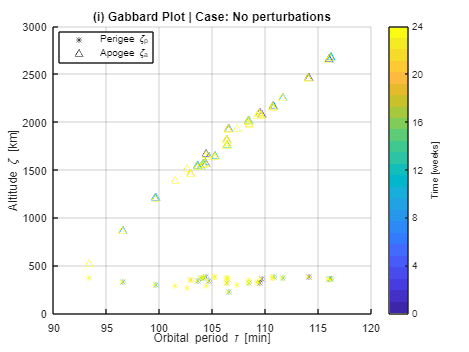

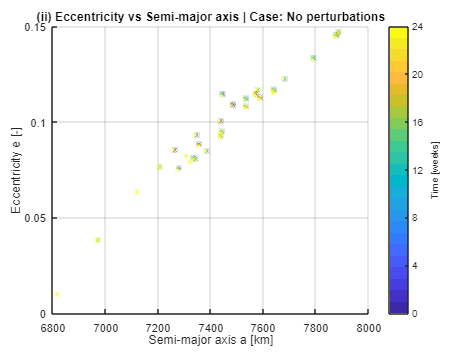

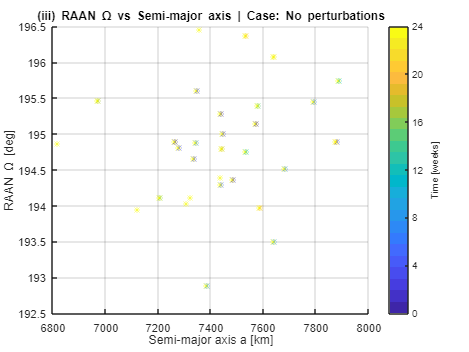

Case: Drag only


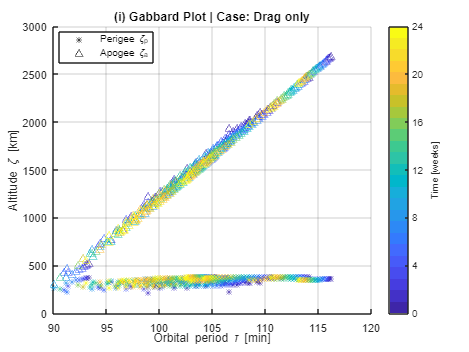

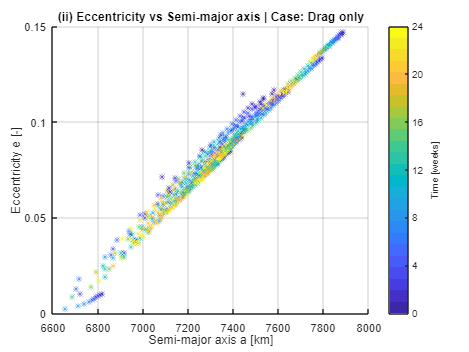

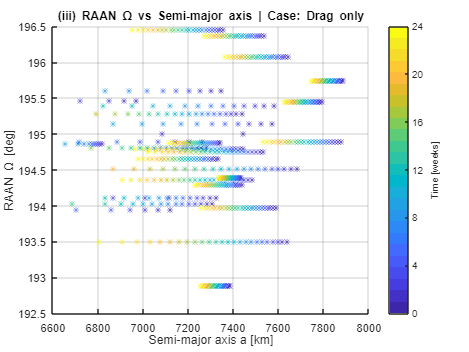

Case: Drag and J2


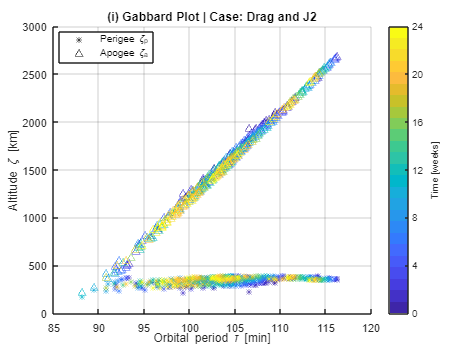

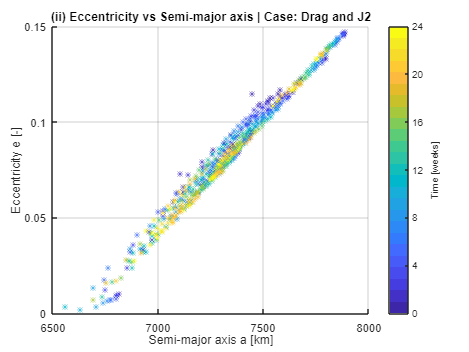

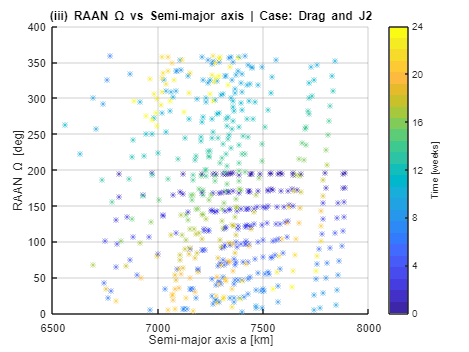

M = 6*4; % (6 months in weeks)

t = linspace(0, 3600*24*7*4*6, M+1); % [s] time

% Defining the 3 cases to implement a loop:
case_names = {'No perturbations', 'Drag only', 'Drag and J2'};
flag_drag_list = [false, true,  true ];
flag_J2_list   = [false, false, true ];

fig_num = 1; % figure counter
close all

% Storage for animation (3 cases)
a_M_all     = zeros(M+1, N, 3);
e_M_all     = zeros(M+1, N, 3);
Omega_M_all = zeros(M+1, N, 3);
tau_all     = zeros(M+1, N, 3);
r_p_all     = zeros(M+1, N, 3);
r_a_all     = zeros(M+1, N, 3);

for c = 1:3 %"c" for "case"

    % Pick flags for this case
    flag_drag = flag_drag_list(c);
    flag_J2   = flag_J2_list(c);

    % Pre-allocation of the arrays
    r       = zeros(3, M+1);
    v       = zeros(3, M+1);
    r_store = zeros(3, M+1, N);  % [km] (3 x time x fragments)
    % All orbital element arrays share the same size (M+1, N)
    [a_M, e_M, Omega_M, i_M, omega_M, theta_M, tau, r_p, r_a, zeta_p, zeta_a] = deal(zeros(M+1, N));

    for j = 1:N % <-- for every piece
        % Find position and velocity:
        [r, v] = functionshw3.cowell(r0(:,j), v0(:,j), bc(j), t, flag_drag, flag_J2); % [km, km/s]
        r_store(:, :, j) = r;  % store full trajectory of fragment j

        for k = 1:(M+1) % <-- for every week
            [a, e, Omega, i, omega, theta] = functionshw3.rv2coe(r(:,k), v(:,k), mu_Earth); 
            % [km,-,rad,rad,rad,rad]

            % Saving results:
            a_M(k,j)     = a;                                  % [km] semi-major axis
            e_M(k,j)     = e;                                  % [-] eccentricity
            Omega_M(k,j) = Omega;                              % [rad] RAAN
            i_M(k,j)     = i;                                  % [rad] inclination
            omega_M(k,j) = omega;                              % [rad] argument of pericenter
            theta_M(k,j) = theta;                              % [rad] true anomaly
            % [a_M(k,j), e_M(k,j), Omega_M(k,j), i_M(k,j), omega_M(k,j), theta_M(k,j)] = ...
            %     functionshw3.rv2coe(r(:,k), v(:,k), muE); % [km,-,rad,rad,rad,rad]

            [r_p(k,j), r_a(k,j)] = functionshw3.coe2pa(a, e); % [km, km]

            tau(k,j)     = 2*pi*sqrt(a_M(k,j)^3/mu_Earth);                 % [s] orbital period
            zeta_p(k,j)  = r_p(k,j) - R_Earth;                      % [km] perigee altitude
            zeta_a(k,j)  = r_a(k,j) - R_Earth;                      % [km] apogee altitude
        end
    end

    % plotting section
    disp(['Case: ' case_names{c}])

    functionshw3.figures(zeta_a, zeta_p, tau, a_M, e_M, Omega_M, case_names, c)

    % THE COMMENT FOR THE PLOTS ARE BELOW THE PLOTS!

end % end for cases (c)

## Discussion

### Case 1: No perturbations

    In the absence of any perturbation, the debris cloud evolves under the two body keplerian dynamics. Since all fragments share the same initial position $r_0$ differing only in their initial velocity, meaning that the elements computed at time equal zero already reflect the full spread of the cloud which remains constant in time for the entire 6 month simulation.

In the Gabbard plot, the perigee altitude $\zeta_p$ is almost constant across all items. This makes sense since the explosion produces a velocity dispersion symmetric around the satellite's velocity, meaning that fragments that gain energy **raise** their apogee, but their perigee remains close to that of the parent satellite since it is tied to the original orbit.

The apogee alitutde $\zeta_a$, on the other hand, are spread out and fall along a "linear" trend with the orbital period $\tau$. This makes sense since a larger semi-major axis implies a longer period and a higher apogee.

    In the e vs a plot, the positive linear shape we observe is a direct consequence of the explosion: a fragment that is impulsed prograde receives more energy (and thus a larger a) and also a higher apogee relative to its perigee, increasing e. The opposite occurs for retrograde impluses.

    The $\Omega$ vs a plot is also static. Without J2, there is no mechanism to precess the orbital plane, so RAAN is conserved for every fragment. The scatter in $\Omega$ reflects only the efects of the out of plane components of the velocity due to the explosion.

### Case 2: Drag Perturbation Only

In the **Gabbard plot**, both perigee and apogee altitudes decrease with time, and the entire cloud migrates toward shorter orbital periods. It is important to note that the apogee drops faster than the perigee. This is the effect of drag circularization: drag at perigee reduces the apogee on each obit, gradually decreasing eccentricity while the perigee itself decreases slowly. As the orbit circularizes, the perigee also begins to decay the the fragments "reenters".

In the **e vs a** plot, the cloud migrates down and to the left which is consistent with the circularization and energy dissipation described above. The initial diagonal correlation is preserved in shape but compressed toward lower values as time progresses.

The $\Omega$ vs a plot shows that RAAN remains almost constant for each fragment, while a decreases, drifting to the left. This is expected: drag acts along the velocity vector and has no out of plane component, so it induces no torque on the orbital plane and RAAN is not perturbed by drag alone.

### Case 3: Drag and J2 Perturbations

The addition of the J2 perturbation introduces a secular precession of the right ascension of the ascending node $\Omega$. The J2-induced RAAN drift rate is: 


$$\dot{\Omega} = -\frac{3}{2}\frac{nJ_2R_E^2}{p^2}cos(i)$$


or a prograde orbit (i = 54º, cos i > 0), this gives a **westward **(negative) precession of RAAN. Since each fragment has different semi-major axis a (and hence different n and p), each fragment precesses at a slightly different rate, causing the initially compact RAAN distribution to spread and loop over 6 months.

In the **Gabbard plot** and **e vs a** plot, the behavior is qualitatively identical to the drag-only case. Althought the decay is faster and more pronounced, which may be easier to appreciate when comparing both cases in the animations provided.

## Copilot AI

Copilot AI was used throughout the realization of this homework. It was used specifically to understand the homework's wording, and as aiding in the implementation of the theory found in the slides into MATLAB. The promps had to be modified but we found a good way to get straight forwards answer most of the time after a couple of tries. Promts as the following were used: "Using these slides, implement equation "A" going step by step and defining everything explicitly". This gave us a clear idea of how to do the program. Finally, Copilot aided to compact the code, found redundant lines of code as well as debugging.